clc;clear all;close all

# EVACES 2025

% Load the data

Seq = 1; % 1, 2 or 3
downSampling =10; %100 ;
% 10 - good for FB (bad for AugDMD) higher sampling freq
% 100 - good for AugDMD (bad for FB) lower sampling freq
data = load("data\Seq"+num2str(Seq)+".mat");

G1 = downsample(data.G1V3,downSampling);
G2 = downsample(data.G2V3,downSampling);
G3 = downsample(data.G3V3,downSampling);
G4 = downsample(data.G4V3,downSampling);
G5 = downsample(data.G5V3,downSampling);
time = downsample(data.Time,downSampling)';

% we calculate the delta of time
dt = time(2)-time(1);


## Prepare data for DMD

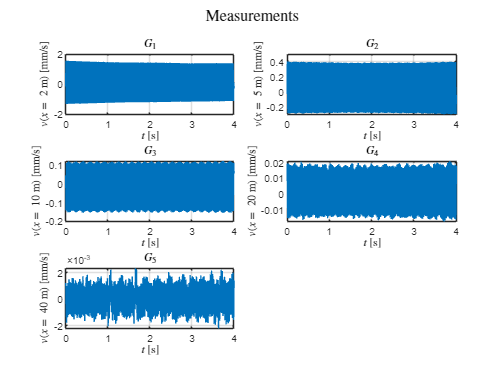

i0 = 1;
numSamples = 80000;%8000;
% 80000 for 4 sec in downsampling 10
% 8000 for 4 sec in downsampling 100
window = 1:numSamples;

f = [G1(window)'; G2(window)'; G3(window)'; G4(window)'; G5(window)'];
meas_points = [2 5 10 20 40];

% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')
sgtitle('Measurements','Interpreter','latex')

## Noise analysis

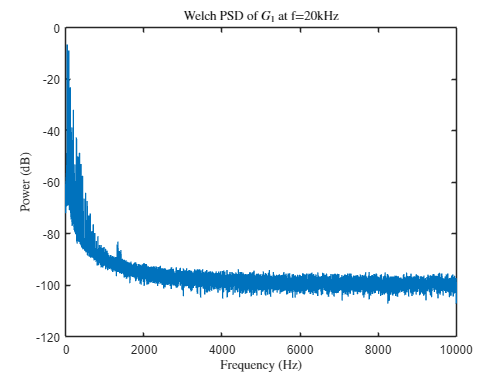

figure;
[Pxx, f_welch] = pwelch(f(1,:), [], [], [], 1/dt);
plot(f_welch, 10*log10(Pxx));
% plot(f_welch, Pxx);
xlabel('Frequency (Hz)', 'Interpreter','latex'); 
ylabel('Power (dB)', 'Interpreter','latex');
title("Welch PSD of $G_1$ at f=" + int2str((1/dt)/1000)+"kHz",'Interpreter','latex')

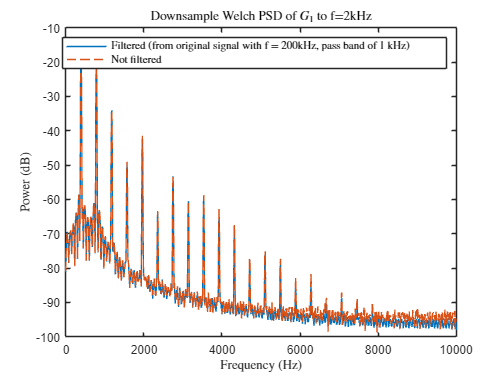




figure
data_filtered = lowpass(f(1,:), 100, 1/dt);  % Low-pass filter at 1kHz
data_downsampled_filtered = downsample(data_filtered, 10);
[Pxx_filter, f_welch_filter] = pwelch(data_downsampled_filtered, [], [], [], 1/dt);
plot(f_welch_filter, 10*log10(Pxx_filter));
% plot(f_welch, Pxx);
hold on
data_downsampled_no_filtered = downsample(f(1,:),10);
[Pxx_no_tiler, f_welch_no_filter] = pwelch(data_downsampled_no_filtered, [], [], [], 1/dt);
plot(f_welch_no_filter, 10*log10(Pxx_no_tiler),'--');

xlabel('Frequency (Hz)', 'Interpreter','latex'); 
ylabel('Power (dB)', 'Interpreter','latex');
title("Downsample Welch PSD of $G_1$ to f=" + int2str((1/dt)/10000)+"kHz",'Interpreter','latex')
legend({'Filtered (from original signal with f = 200kHz, pass band of 1 kHz)','Not filtered'},'Interpreter','latex')

## Standard DMD

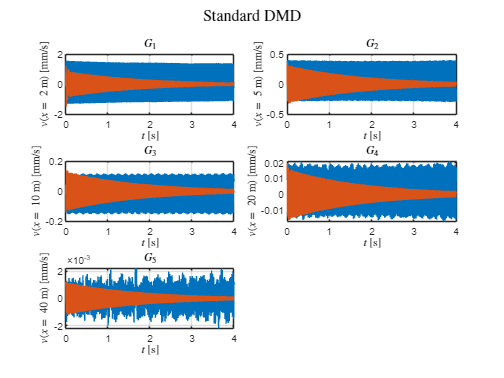

%% DMD for clean signal

% Rank truncation
r = 5;

X1 = f(:,1:end-1); X2 = f(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U, S, V] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde_Standard = Ur' * X2 * Vr *Sr^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W, D] = eig(Atilde_Standard);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi = X2 * Vr / Sr * W;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda = diag(D);
omega = log(lambda) / dt;

% Determine the initial condition (b) in DMD space
b = Phi \ X1(:, 1);

% DMD prediction
f_dmd = real(Phi*(b.*exp(omega*time(window))));

% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
hold on
plot(time(window),f_dmd(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
hold on
plot(time(window),f_dmd(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
hold on
plot(time(window),f_dmd(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
hold on
plot(time(window),f_dmd(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
hold on
plot(time(window),f_dmd(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')

sgtitle('Standard DMD','Interpreter','latex')

## AugDMD

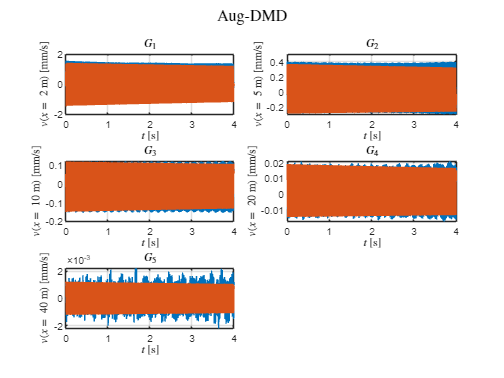


% Rank truncation
r = 5;

s = 100;
l = ceil((length(f))/2);

for i = 1:s
    f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
        f(3,i:l+i-1) ; f(4,i:l+i-1) ; f(5,i:l+i-1) ];
end

X1_aug = f_aug(:,1:end-1); X2_aug = f_aug(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U_aug, S_aug, V_aug] = svd(X1_aug, "econ");

% Truncate the SVD to the desired rank 'r'
Ur_aug = U_aug(:, 1:r);
Sr_aug = S_aug(1:r, 1:r);
Vr_aug = V_aug(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde_aug = Ur_aug' * X2_aug * Vr_aug *Sr_aug^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W_aug, D_aug] = eig(Atilde_aug);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_aug = X2_aug * Vr_aug / Sr_aug * W_aug;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda_aug = diag(D_aug);
omega_aug = log(lambda_aug) / dt;

% Determine the initial condition (b) in DMD space
b_aug = Phi_aug \ X1_aug(:, 1);

% DMD prediction
f_dmd_aug = real(Phi_aug*(b_aug.*exp(omega_aug*time(window))));

% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
hold on
plot(time(window),f_dmd_aug(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
hold on
plot(time(window),f_dmd_aug(s+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
hold on
plot(time(window),f_dmd_aug(s*2+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
hold on
plot(time(window),f_dmd_aug(s*3+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
hold on
plot(time(window),f_dmd_aug(s*4+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')
sgtitle('Aug-DMD','Interpreter','latex')

## Forward-backwards DMD

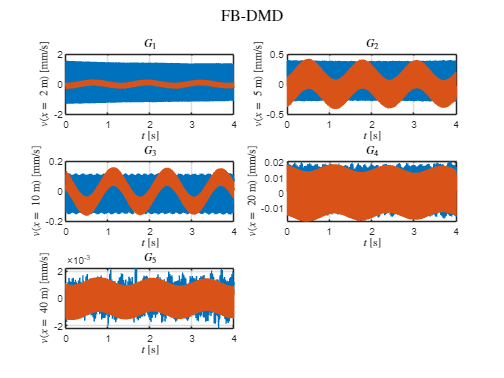

%% DMD for clean signal

% Rank truncation
r = 5;

X1 = f(:,1:end-1); X2 = f(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U_f, S_f, V_f] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur_f = U_f(:, 1:r);
Sr_f = S_f(1:r, 1:r);
Vr_f = V_f(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
f_Atilde = Ur_f' * X2 * Vr_f *Sr_f^(-1);

[U_b, S_b, V_b] = svd(X2, "econ");

Ur_b = U_b(:, 1:r);
Sr_b = S_b(1:r, 1:r);
Vr_b = V_b(:, 1:r);

b_Atilde = Ur_b' * X1 * Vr_b *Sr_b^(-1);

% Atilde_FB = (f_Atilde*inv(b_Atilde))^0.5;
Atilde_FB = sqrtm(f_Atilde * pinv(b_Atilde));

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W_fb, D_fb] = eig(Atilde_FB);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_fb = X2 * Vr_f / Sr_f * W_fb;
% Phi_fb = 0.5 * (X1 * Vr_f / Sr_f * W_fb + X2 * Vr_b / Sr_b * W_fb);

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda_fb = diag(D_fb);
omega_fb = log(lambda_fb) / dt;

% Determine the initial condition (b) in DMD space
b_fb = Phi_fb \ X1(:, 1);

% DMD prediction
f_dmd_fb = real(Phi_fb*(b_fb.*exp(omega_fb*time(window))));


% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
hold on
plot(time(window),f_dmd_fb(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
hold on
plot(time(window),f_dmd_fb(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
hold on
plot(time(window),f_dmd_fb(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
hold on
plot(time(window),f_dmd_fb(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
hold on
plot(time(window),f_dmd_fb(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')

sgtitle('FB-DMD','Interpreter','latex')